# Assignment 1: Optics / Snell

*Pratheep Kumar Chelladurai*

Please “check the math” on this. Assume the equilateral prism is made of flint glass, whose index of refraction *n* depends on wavelength according to the table below. The white light angle of incidence is 55° from normal.

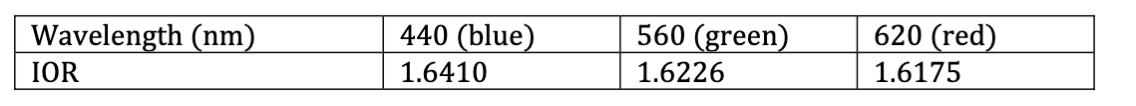

### Question 1a:

*What percent of the unpolarized incident light, at each wavelength, is reflected from the first surface of the prism (see Eqs 1.1-1.3)?*

%n surface calcualtion
n_material = [1.6410 1.6226 1.6175];
n_air = 1;
angle_incidence = 55;
surface_reflection = zeros(3,0);

for i = 1 : length(n_material)

r_parallel = ((cosd(angle_incidence) - ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)) ...
    / ...
    (cosd(angle_incidence) + ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)))^2 ;


r_perpendicular = ((((n_material(i)/n_air)^2)*(cosd(angle_incidence)) - ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)) ...
    / ...
    (((n_material(i)/n_air)^2)*(cosd(angle_incidence)) + ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)))^2 ;

surface_reflection(i) = ((r_parallel + r_perpendicular ) / 2) * 100;

end

surface_reflection_table = array2table(surface_reflection);
surface_reflection_table.Properties.VariableNames = {'Blue (in %)';...
    'Green (in %)';'Red (in %)'};
surface_reflection_table

surface_reflection_table = 1×3 table
    Blue (in %)    Green (in %)    Red (in %)
    ___________    ____________    __________

      9.1223          8.8461         8.7693  


### Question 1b:

*What are the three angles of transmission, corresponding to the tabulated wavelengths, inside the prism (see Snell’s Law, Eq 1.5)?*

angle_of_transmission = zeros(3,0);
for i = 1:length(angle_of_transmission)
    angle_of_transmission(i) = asind((n_air/n_material(i))*sind(angle_incidence))
end

### Question 1c:

*What are the three angles of transmission, corresponding to the tabulated wavelengths, inside the prism (see Snell’s Law, Eq 1.5)?*